## Image Resizing

imageResizingNeeded = false;

if imageResizingNeeded
    srcFiles = dir('TrafficSignDataset\*.png');
    for i = 1 : length(srcFiles)
        filename = strcat('TrafficSignDataset\',srcFiles(i).name);
        im = imread(filename);
        k=imresize(im,[800,800]);
        %6,11class k=imresize(im,[300,400]);  
        newfilename=strcat('resizedTrafficSignDataset\',srcFiles(i).name);
        %6,11Class  newfilename=strcat('resizedTrafficSignDataset\',srcFiles(i).name);
        imwrite(k,newfilename,'png');
    end
end

## Create Ground Truth

needGroundTruth = false;

if needGroundTruth
    imageLabeler('resizedTrafficSignDataset')
end

## Load Ground Truth

load('labelData\1Class.mat'); %อยากได้จำนวน class อะไรก็โหลดอันนั้นมา
currentPathDataSource = ('D:\Diary\Year 3-2\Com Vis\Project\TrafficSign Detection\resizedTrafficSignDataset');
%6Class currentPathDataSource = ("D:\Diary\Year 3-2\Com Vis\Project\Testingจ้าา\reSet1x");
%11Class currentPathDataSource = ("D:\Diary\Year 3-2\Com Vis\Project\Testingจ้าา\reSet1"); 

newPathDataSource = fullfile("resizedTrafficSignDataset");
%6,11 Class newPathDataSource = fullfile("resizedTrafficSignDataset2");

alternativePaths = {[currentPathDataSource newPathDataSource]};
unresolvedPaths = changeFilePaths(gTruth,alternativePaths);
dataS = gTruth;
signDataset = objectDetectorTrainingData(dataS);
signDataset(1:4,:)

ans = 4×2 table
                              imageFilename                                 trafficSign    
    _________________________________________________________________    __________________

    {'C:\Users\sarun\Desktop\TSD1\resizedTrafficSignDataset\001.png'}    {[151 253 63 112]}
    {'C:\Users\sarun\Desktop\TSD1\resizedTrafficSignDataset\002.png'}    {2×4 double      }
    {'C:\Users\sarun\Desktop\TSD1\resizedTrafficSignDataset\003.png'}    {5×4 double      }
    {'C:\Users\sarun\Desktop\TSD1\resizedTrafficSignDataset\004.png'}    {3×4 double      }


## **Create train, validation, test data table**

rng(0);
shuffledIndices = randperm(height(signDataset));
idx = floor(0.6 * length(shuffledIndices) );

trainingIdx = 1:idx;
trainingDataTbl = signDataset(shuffledIndices(trainingIdx),:);

validationIdx = idx+1 : idx + 1 + floor(0.1 * length(shuffledIndices) );
validationDataTbl = signDataset(shuffledIndices(validationIdx),:);

testIdx = validationIdx(end)+1 : length(shuffledIndices);
testDataTbl = signDataset(shuffledIndices(testIdx),:);

## **Create train, validation, test data store**

imdsTrain = imageDatastore(trainingDataTbl{:,'imageFilename'});
bldsTrain = boxLabelDatastore(trainingDataTbl(:,'trafficSign'));
%6Class bldsTrain = boxLabelDatastore(trainingDataTbl(:,2:7));
%11Class bldsTrain = boxLabelDatastore(trainingDataTbl(:,2:12));

imdsValidation = imageDatastore(validationDataTbl{:,'imageFilename'});
bldsValidation = boxLabelDatastore(validationDataTbl(:,'trafficSign'));
%6Class bldsValidation = boxLabelDatastore(validationDataTbl(:,2:7));
%11Class bldsValidation = boxLabelDatastore(validationDataTbl(:,2:12));

imdsTest = imageDatastore(testDataTbl{:,'imageFilename'});
bldsTest = boxLabelDatastore(testDataTbl(:,'trafficSign'));
%6Class bldsTest = boxLabelDatastore(testDataTbl(:,2:7));
%11Class bldsTest = boxLabelDatastore(testDataTbl(:,2:12));

## **Create train, validation, test dataset**

trainingData = combine(imdsTrain,bldsTrain);
validationData = combine(imdsValidation,bldsValidation);
testData = combine(imdsTest,bldsTest);

## Check Combine object

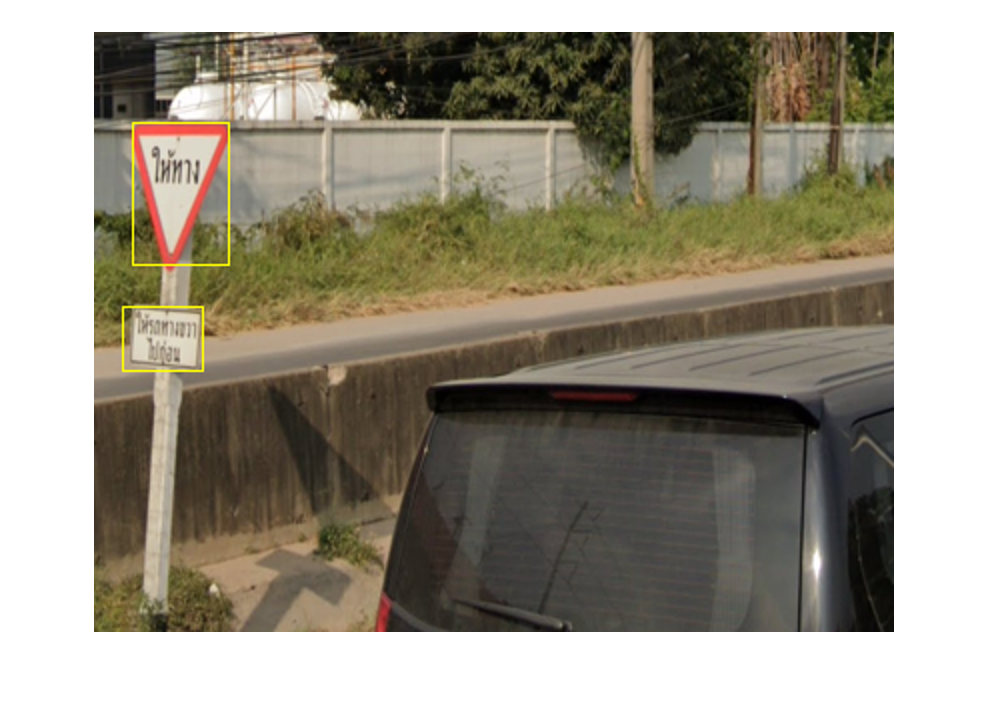

data = read(trainingData);
I = data{1};
bbox = data{2};
annotatedImage = insertShape(I,'Rectangle',bbox);
annotatedImage = imresize(annotatedImage,2);
figure
imshow(annotatedImage)